# Higgs Classification

**Megan Miyasaki **

Partner: Kuan Lee

In this problem we are going to look at an inclusive search for the standard model Higgs boson in pp collisions at √ s = 13 TeV at the LHC using simulated data [[A. Schuy](https://github.com/AlexSchuy/qsvm_jet_tagging/tree/master/qsvm_jet_tagging/generation)]. The Higgs bosons are produced with large transverse momentum (pT) and decaying to a bottom quark-antiquark pair. The Higgs candidates could be reconstructed as large-radius jets using Calorimeters. Due to large QCD backgorund containmination, the direct 5-sigma observation of this Higgs channel is not accomplished yet[[Phys. Rev. Lett. 120, 071802 (2018)](https://arxiv.org/abs/1709.05543)]. We are going to use a set of training datasets to optimize event selections in order to enhance the discovery sensitivity. The optimal event selections will be applied to a selected pseudo-experiment data.

Both of you will use the same training samples for analysis. Each sample contains 14 features: ‘pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', 't1', 't2', 't3', 't21', 't32', 'KtDeltaR' [[Eur. Phys. J. C 79 (2019) 836](https://atlas.web.cern.ch/Atlas/GROUPS/PHYSICS/PAPERS/PERF-2017-04/)]. You can explore different strategies for event selection optimization using training samples. The optimal event selection will be applied to pseudo-experiment data.

# Assignments

**Problem 1:Download the training datasets from one of the two pT-range folders. In each folder, there are 2 files, each containing 100k jets. The signal dataset is labeled as “higgs” and the background dataset is labeled as “qcd.”**

clear;close all;clc;

% downloading and importing the data for problem 1:

h5disp("higgs_100000_pt_250_500.h5"); 

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


signal=h5read("higgs_100000_pt_250_500.h5", '/higgs_100000_pt_250_500');
h5disp("qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


background=h5read("qcd_100000_pt_250_500.h5", '/qcd_100000_pt_250_500');

**Problem 2:Explore the training data by addressing following questions: a. Do all features provide discrimination power between signal and background? b. Are there correlations among these features? c. Compute expected discovery sensitivity by normalizing each sample appropriately. d. Develop a plan to optimize the discovery sensitivity by applying selections to these features.**

For this lab it is important to try and get comfortable with how the LHC searches for the standard model of Higgs boson in pp collisions at sqrt(s) = 13 TeV. First off, simply put, Higgs boson is an elementary particle in the Standard Model of particle physics, produced by quantum excitation of the Higgs field, one of the fields in particle physics theory. We know that Higgs bosons are produced with large transverse momentum and decaying to a bottom quark-antiquark pair, and Higgs candidates could be reconstructed as large radius jets using calorimeters. It is difficult to spot Higgs boson decay channel because there are many other ways of producing bottom quarks in proton-proton collisions. Therefore, making it hard to isolate the Higgs boson decay signal from the background “noise” associated with processes. Though by contrast, the less common Higgs boson decay channels that were observed at the time of discovery of the particle, in other words the decay to a pair of photons, are much easier to extract from the background. In order to extract a signal that will have the direct 5-sigma observation, the ATLAS and CMS collaborated and combined data from their first and seconds runs at the LCH, and applied analysis methods to the data and they were able to detect the decay of Higgs boson to a pair of bottom quarks, that ended to be consistent with the Standard Model prediction.

Now that we have a course and brief understand of what the Higgs boson is, we should understand how the LHC works and it measures and takes data in regards to the Higgs boson. The LHC is the biggest and most powerful particle accelorat in the world, made of a 27-kilometer ring of superconducting magnets as well as some accelerating structures to help boost the energy of particles. These energy boost, help prodcue two high energy beams that travel near the speed of light before the collide with each other from opposite ends of the ring. The LHC is able to accelerate the particles by producing an electric field to boost the particles and create an electromagnetic wave that swithces between postive and negative directions at a specific frequency. Once the particles accelerate to a certain speed they are made to collide with one another in 4 specific locations, ATLAS, ALICE, CMS and LHCb.  To break down what is happening, I will refer to the drawing on the board in the lab, below we see that we use a cyliderical tube to describe the pathway of the particle, withe the z-axis as the direction, and the x and y  axis as the cross section. 

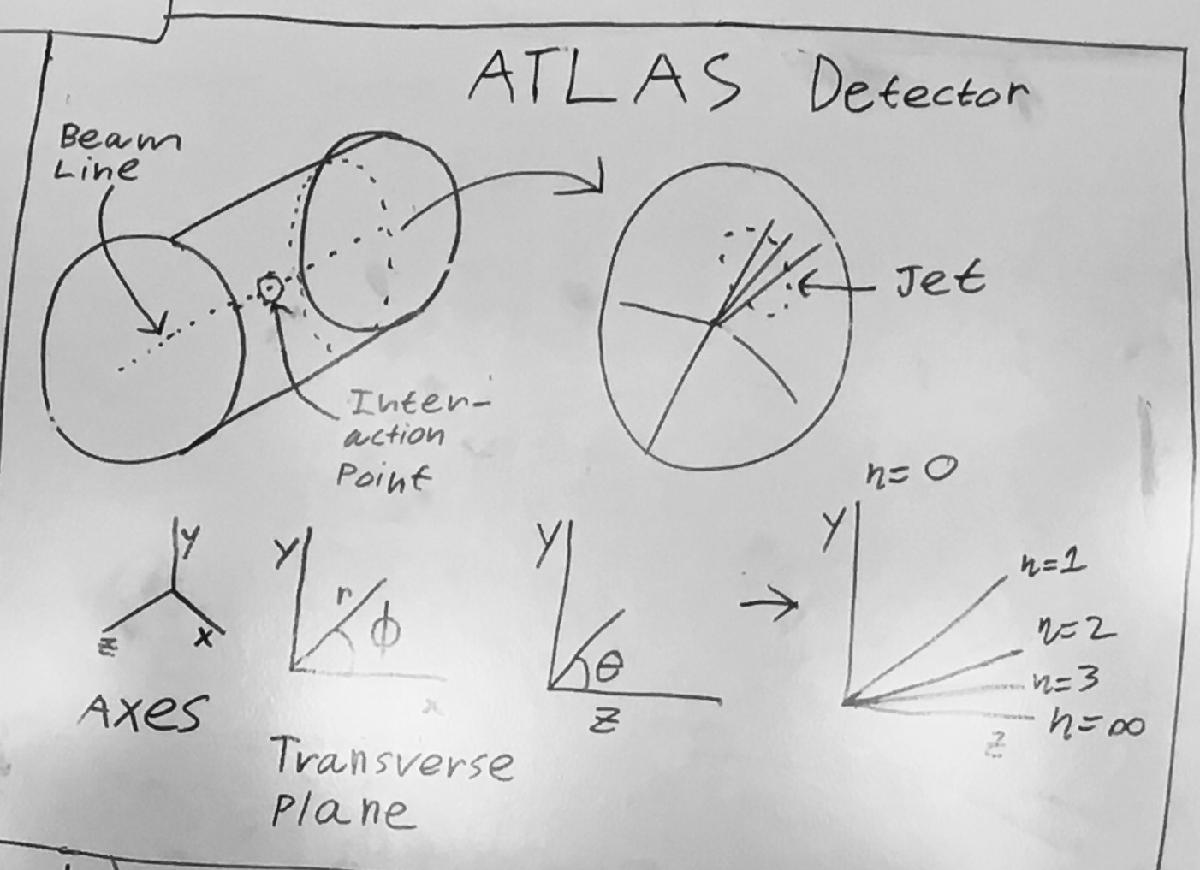

So now in this lab we want **(to)** look at this data and play around with it, explore what **(features)** the data has and how features may correlate to each other. We have been given 14 features to explore and plot with in this data below is a brief explanation for what each feature is and what it does. 

**Short descptions of the 14 features:**

**‘pt’ ~ **$p_t$

The Higgs boson transvers-momentum. Transverse plane, is the xy plane with phi as the angel of measurement. It is calculated from transversal energy, delivered on calorimeters with units GeV. pT,1 and pT,2, the transverse momenta of the two sujet**(subject) **merged in the final step of clustering. 


$$\sqrt{p_x^2 +p_y^2 };P_x^2 =\mathrm{momentum}\;\mathrm{in}\;x\;\mathrm{direction},P_y^2 =\mathrm{momentum}\;\mathrm{in}\;y\;\mathrm{direction}\;$$


**‘eta’ ~ η**

The pseudorapidity  is a commonly used spatial coordinate describing the angle of a particle relative to the beam axis. It is defined as.where is(**define as the angle....**) the angle between the particle three-momentum and the positive direction of the beam axis.


$$\eta =-\ln \left\lbrack \left(\tan \left(\frac{\theta }{2}\right)\right)\right\rbrack$$


**‘phi’ ~ϕ**

The azimuthal angle, which is used for the jet azimuthal angle correlations in the production of Higgs boson pair of two jets at hardon colliders. 


$$\cos^{-1} \left(\frac{x}{r}\right)$$


**‘mass’ ~ m**

The Invariant mass; if the two photons originated from a decaying Higgs boson, their invariant mass can be identified with the mass of the decaying Higgs boson; that is, a Higgs mass of 126GeV


$$\begin{array}{l}
E^2 =p^2 +m^2 ;E\;\textrm{is}\;\textrm{the}\;\textrm{energy}\;\textrm{of}\;\textrm{the}\;\textrm{particle},p\;\textrm{is}\;\textrm{the}\;\textrm{momentum}\ldotp \textrm{We}\;\textrm{can}\;\textrm{then}\;\textrm{rearrange}\;\textrm{the}\;\textrm{equation}\;\textrm{to}\;\\
m^2 =E^2 -p^2 
\end{array}$$


**Subjettiness ~ **$\tau_N$

N-subjettiness variables are defend by clustering the constituents of a jet with the exclusive kt algorithem and requiring that N subjets are found.  Given N subjet axes in a fat jet, N – subjettiness, $\tau_N$is given by 


$$\tau_N =\frac{1}{d_0 }\sum_k P_{T,k} \min \left\lbrace \left\lbrack \Delta R_{1,k} ,\Delta R_{2,k} ,\ldotp \ldotp \ldotp ,\Delta R_{N,k} \right\rbrack \right\rbrace$$


- $\Delta R_{N,k}$ Is the angular separation between constituent k and candidate subjet N 

- $d_o$  is a normalization factor given by: $d_0 =\sum_k P_{T,k} R_0 \;\textrm{so}\;0\le \tau_N \le 1$

- $R_0 =0\ldotp 8$for AK8 clustering. 

Also, ‘t1’,’t2’,’t3’ equate to $\tau_{1,2,3}$, ‘t21’ and ‘t32’ are the Subjettiness ratios 

**‘ee2’ ~e2 & ‘ee3’ ~e3**

The 2-point ECF ratio or the 3-point ECF ratio, with ECF = energy correlation function, therefore ECF ration is the ratio of energy correlation functions. The energy correlation functions are defined with the motivation that (N+1) – point correlators are sensitive to N-prong subtractors. 


$$\begin{array}{l}
e_2 =\sum_{1\le i<j<\textrm{nJ}} Z_i \;Z_j \;R_{\textrm{ij}} \;R_{\textrm{ik}\;} \;\;,\;e_3 \;=\sum_{1\le i<j<k\le \textrm{nJ}} Z_i \;Z_j \;Z_k \;R_{\textrm{ij}} \;R_{\textrm{ik}\;} R_{\textrm{jk}} ,;\\
\textrm{with}\;Z_i \equiv \frac{p_{\textrm{Ti}} }{\sum_{j\epsilon \textrm{jet}} p_{\textrm{Tj}} },R_{\textrm{ij}} =\sqrt{{\left(\phi_i -\phi_j \right)}^2 +{\left(y_i -y_j \right)}^2 }\;;\phi_i =\textrm{azumthal}\;\textrm{angle}\;
\end{array}$$


**‘d2’ ~ D2**

Defined as a double ratio of ECFs, 3-to-2 – point ECF ratio: 


$$D_2 =\frac{e_3 }{{\left.{\left(e\right.}_2 \right)}^3 }$$


**‘angularity’ a3**

Jet mass (M), width, eccentricity, planar flow and angularity are measured for jets reconstructed using the anti-kt algorithm with distance parameters R=0.6 and 1.0, with transverse momentum pT>300  GeV and pseudorapidity |η|<2.

The formula of angularity is:


$$\begin{array}{l}
\tau_a =\frac{1}{M}\sum_i E_i \sin^a \theta_i \;{\left\lbrack 1-\cos \left(\theta_i \right)\right\rbrack }^{1-a} \\
\textrm{where}\;M\;\textrm{is}\;\textrm{the}\;\textrm{jet}\;\textrm{mass}\;\textrm{and}\;a\;\textrm{is}\;\textrm{the}\;\textrm{parameter}\;\textrm{that}\;\textrm{can}\;\textrm{be}\;\textrm{chosen}\;\textrm{to}\;\\
\textrm{emphasis}\;\textrm{radiation}\;\textrm{near}\;\textrm{the}\;\textrm{edges}\;\left(a<0\right)\;\textrm{or}\;\textrm{core}\left(a>0\right)\ldotp 
\end{array}$$


**‘KtDeltaR ~ kt** **Δ****R**

ΔR of two subjects within the large-R jet with the kt splitting scale, this variable is obtained by reclustering the constituents of a jet with kt algorithm, which usually clusters last the harder constituents, and  then taking the kt distance measure between the two subject at the final stage of the recombination procedure. As well, ΔR the corresponding angular separation 

**Now I will go into the exploration of the data and plot some graphs to see how the data compares with one another. **

## Plotting and exploring the data and their relations:

As mentioned in lab section, only the first few features seem to have an importance we want to look at therefore, I will compare the singal and the background of each of the features, pt, eta, phi, mass, d2, angularity, t32(subjettiness ratio), and ktdeltaR.

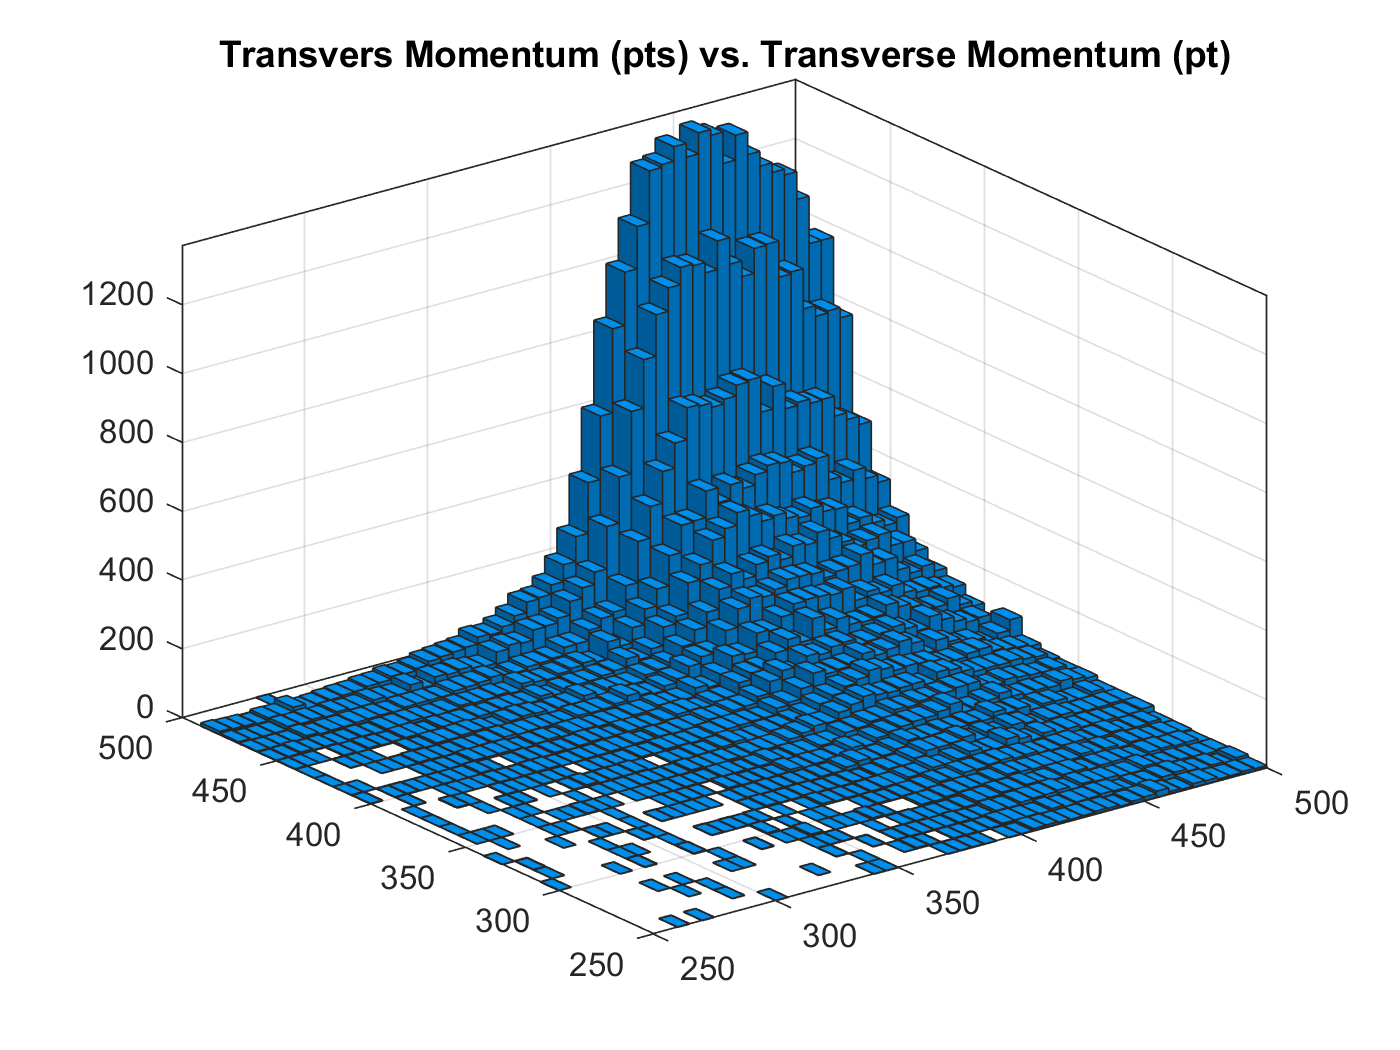

%first try looking at the data: pt, between higgs and qcd
pt=background(1,:);
pts=signal(1,:);

histogram2(pt,pts);
title('Transvers Momentum (pts) vs. Transverse Momentum (pt)')
hold off 

I cannot see a very good comparsison or data between the two, I will plot them in a different manner

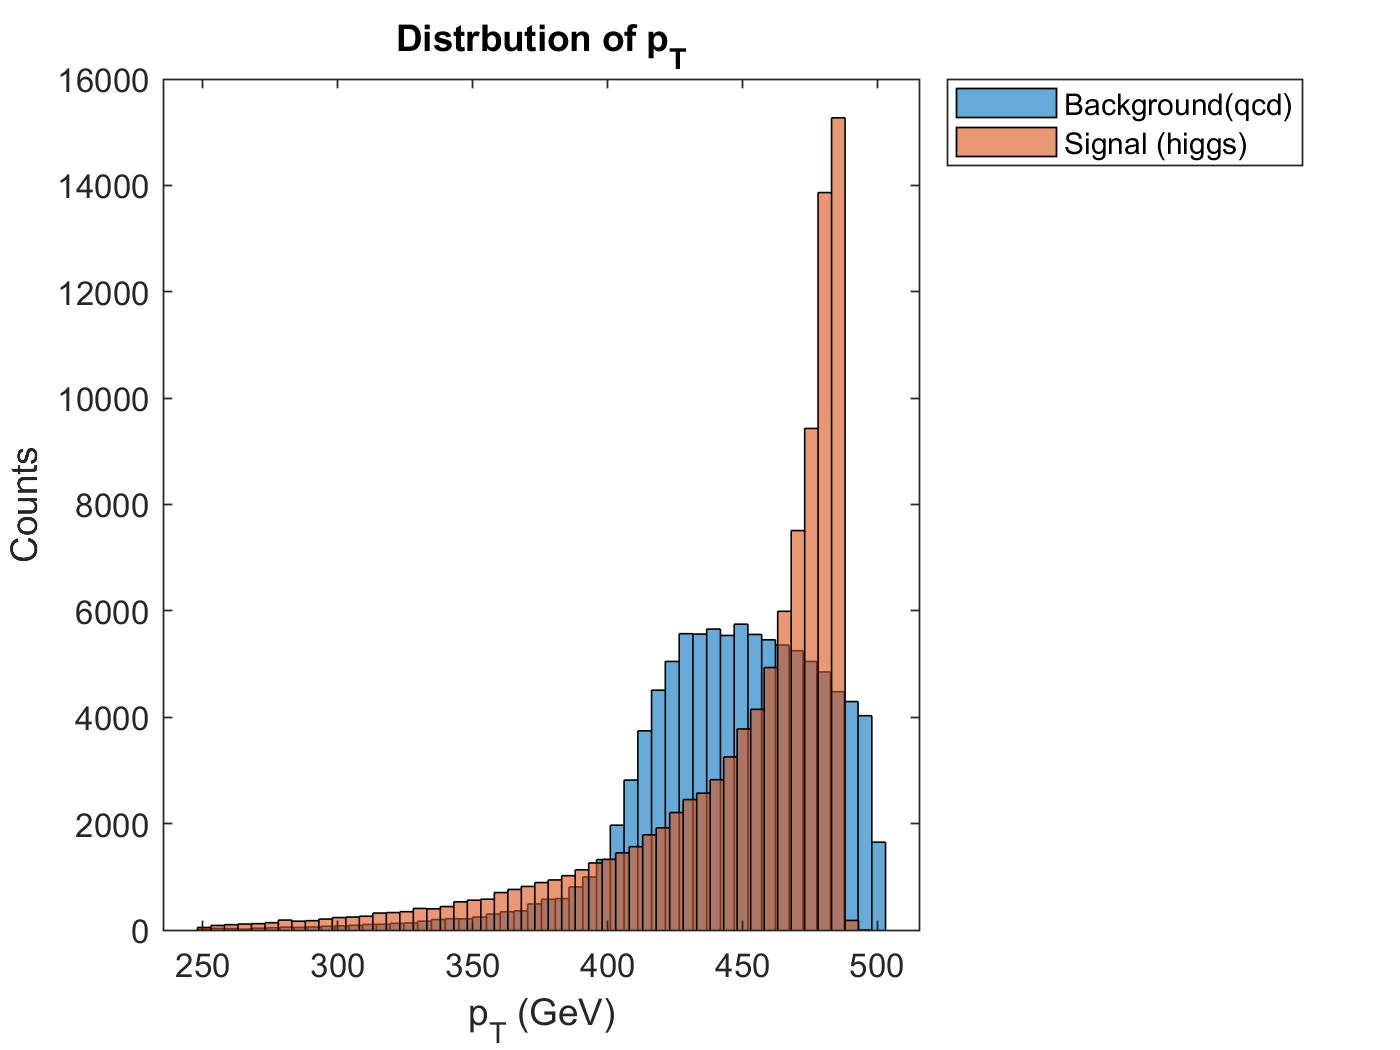

% second try: pt, between higgs and qcd
histogram(pt,50)
hold on 
histogram(pts,50)
legend('Background(qcd)','Signal (higgs)')
title('Distrbution of p_{T}')
ylabel('Counts')
xlabel('p_{T} (GeV)')
hold off

From here we see a better pattern  and distribution, for the rest of the report I will continue to use this type of plotting. From here we can see the distribution are different, the signal is more exponential in growth, and the background noise is more a Rayleigh distribution, if you look carefully you can see the tail for the bakground from the left. 

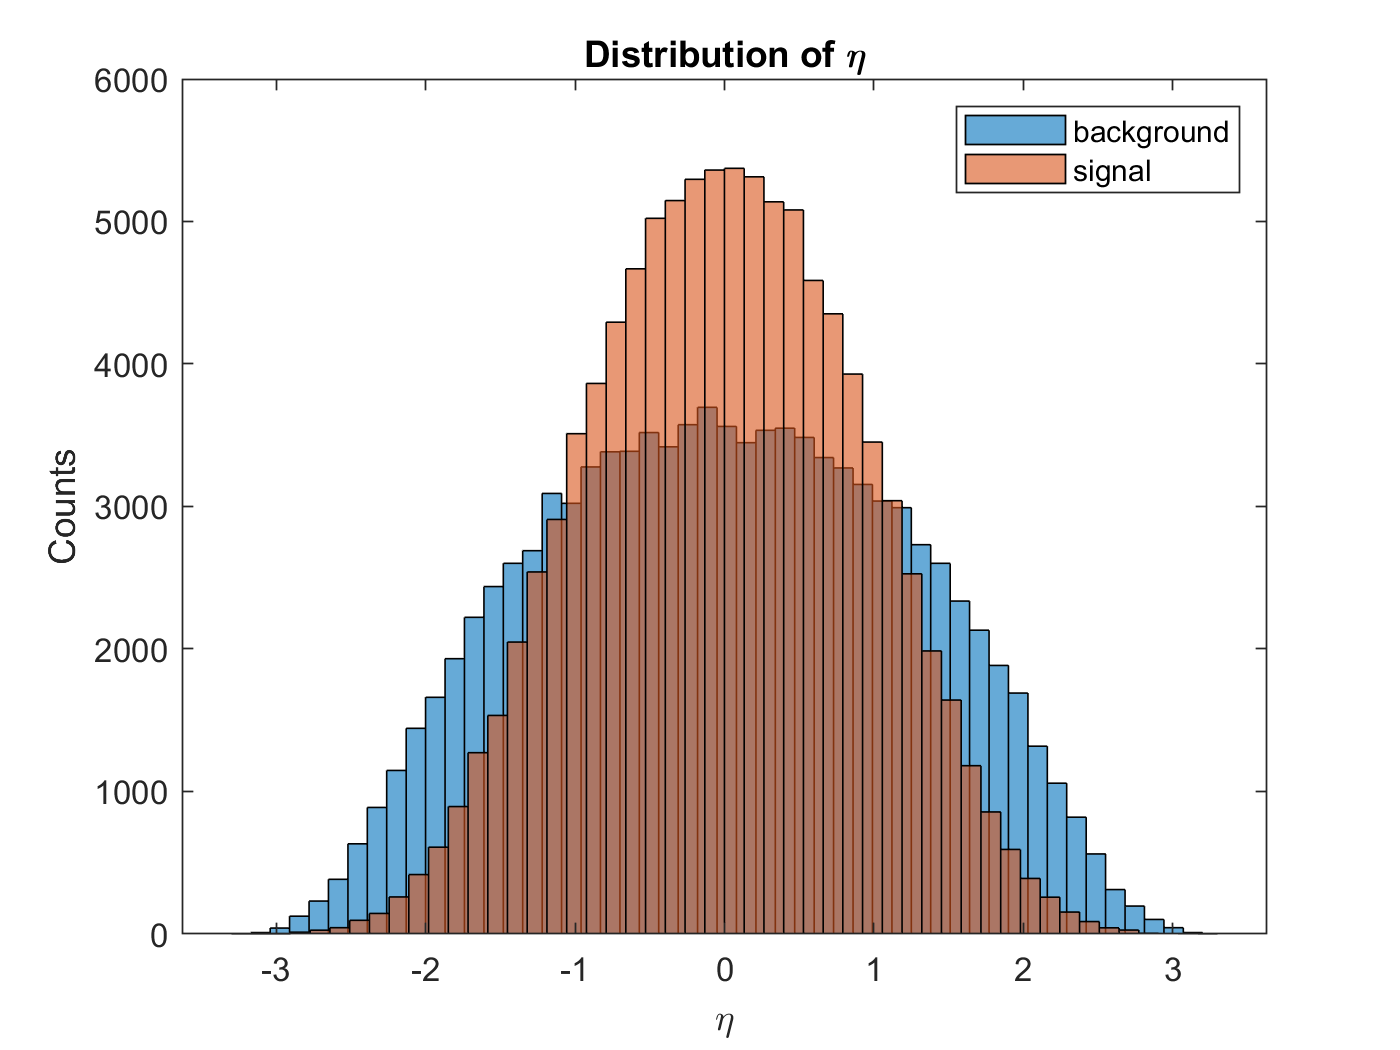

% plot eta of background and signal 
eta=background(2,:);
etas=signal(2,:);

histogram(eta,50);
hold on
histogram(etas,50);
legend('background','signal')
title('Distribution of \eta')
ylabel('Counts')
xlabel('\eta')
hold off

From this we see that both backgrounds are Gaussian, centered at 0, while the background is wider and shorter, and the signal is narrow and taller, they both have the same distribtuion. From earlier we know the relation between eta and pt, and this data suggests that the angles of the particl trajectoreis of the signal are smaller than the angles of the background. 

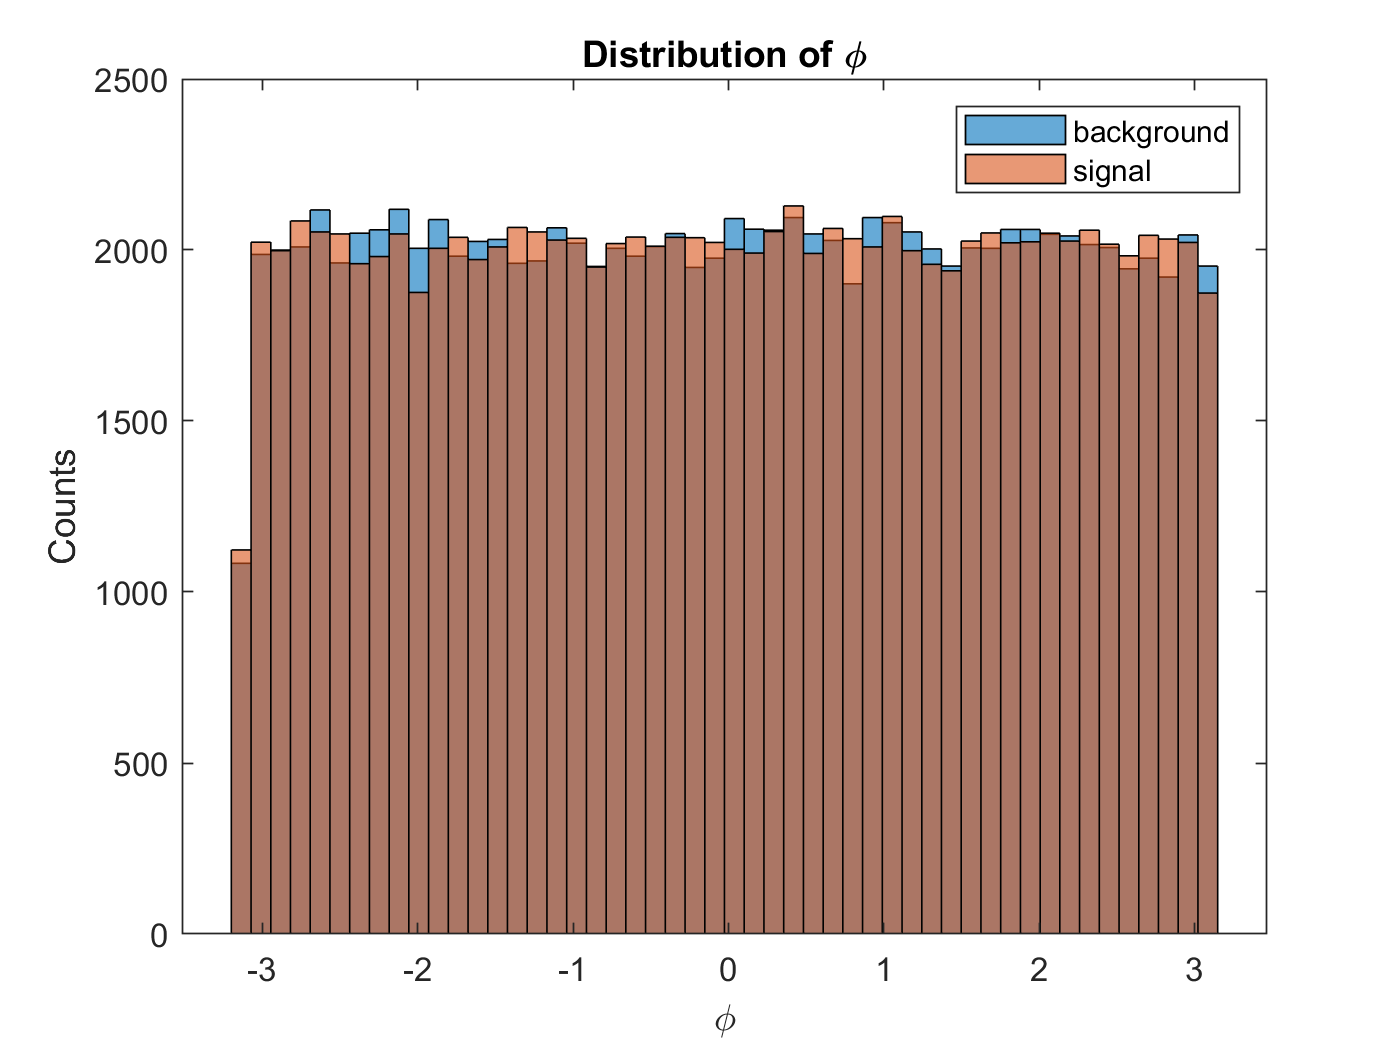

% Comparing the phi, b/c we saw angle played a role. 
phi=background(3,:);
phis=signal(3,:);

histogram(phi,50)
hold on
histogram(phis,50)
legend('background','signal')
title('Distribution of \phi')
ylabel('Counts')
xlabel('\phi')
hold off

 The distribution of the azumthal angle are pretty similar and even, seeing as the particles have a head on collision it would make sense that their angles after are similar. **(can you elaborate more on why a head on collsion will make the distribution of phi even?)**

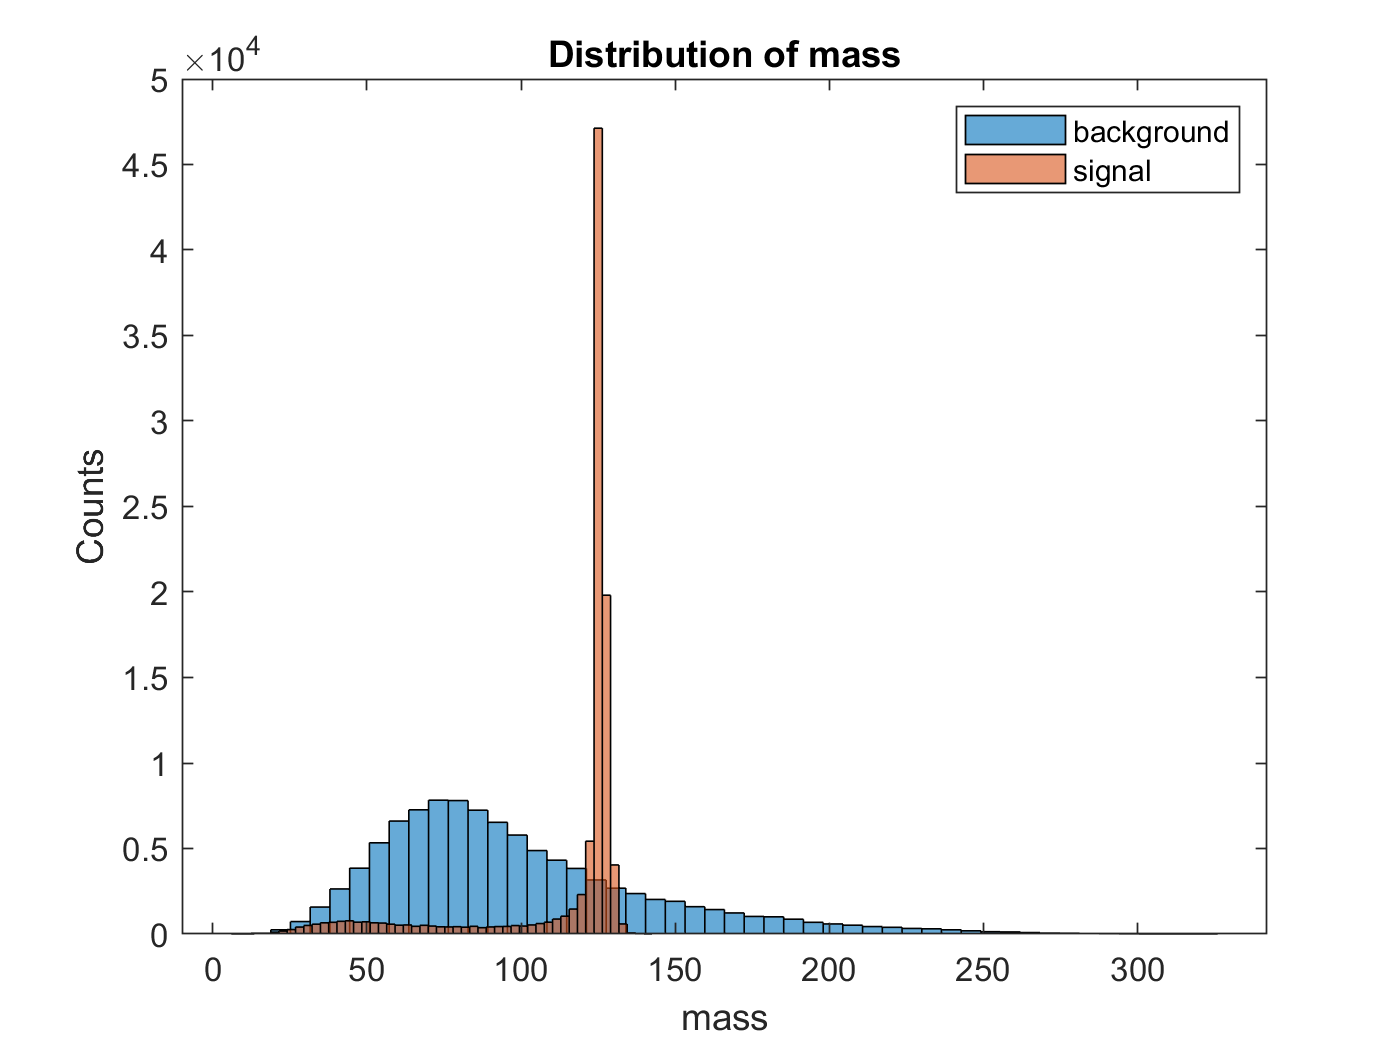

%mass comparison 
mass=background(4,:);
masss=signal(4,:);

histogram(mass,50);
hold on
histogram(masss,50);
legend('background','signal')
title('Distribution of mass')
ylabel('Counts')
xlabel('mass')
hold off

The mass distribution between background and signal is pretty intersting as they are so different. Something to look into as we go further into this data. 

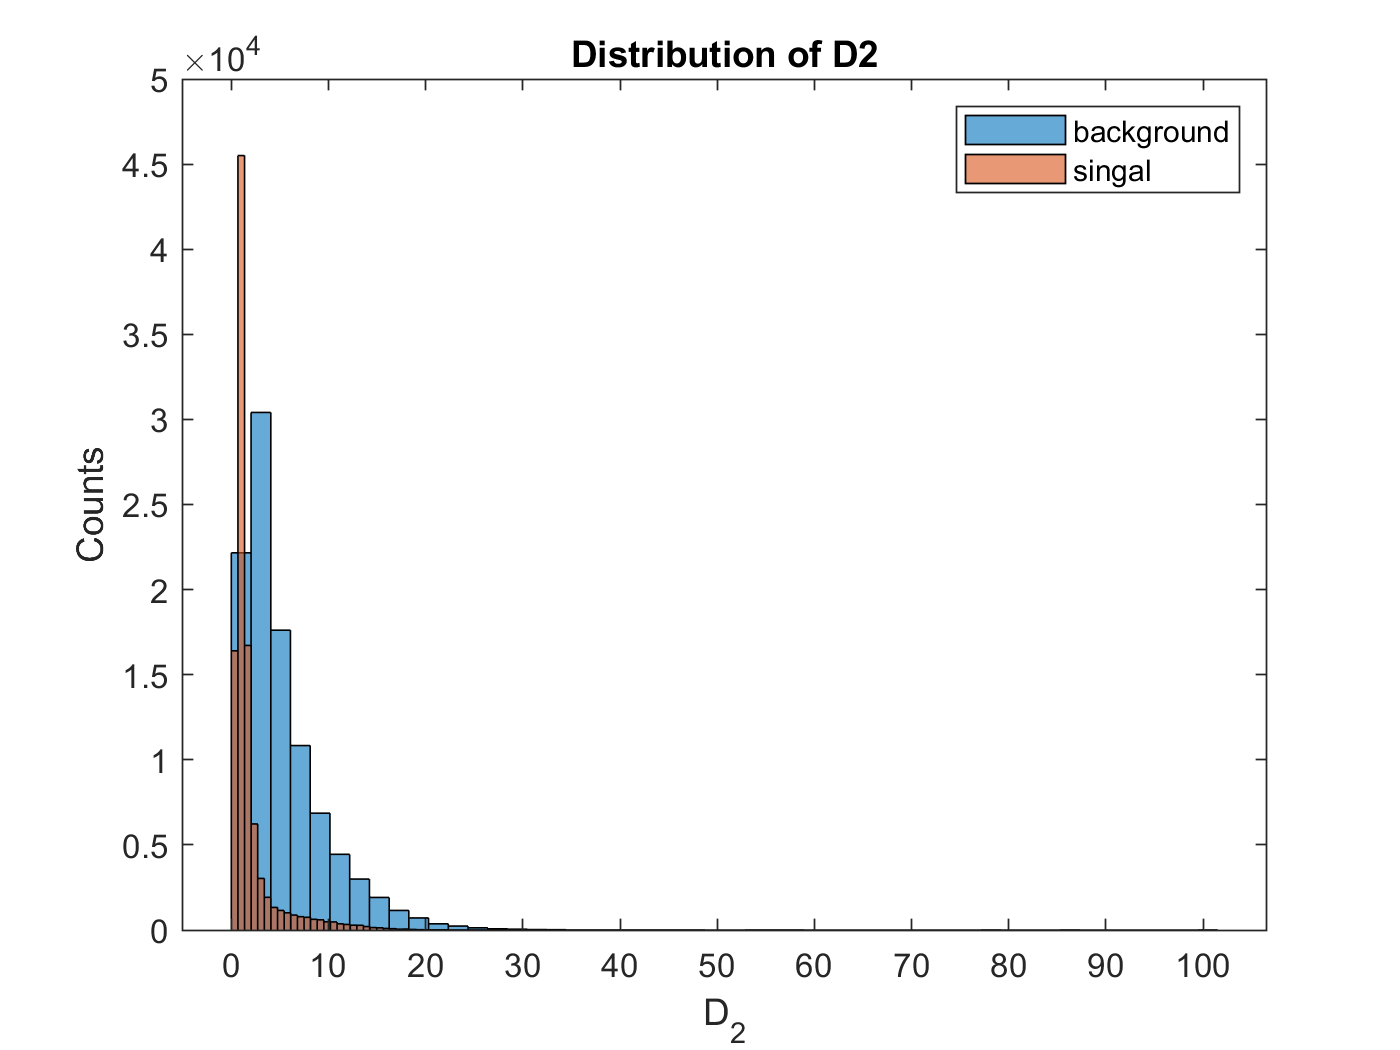

% comparing d2 background and signal 
d2=background(7,:);
d2s=signal(7,:);

histogram(d2,50)
hold on
histogram(d2s,50)
legend('background','singal')
title('Distribution of D2')
ylabel('Counts')
xlabel('D_{2}')
hold off

Both distributions seem to havean exponential decay, the signal decays faster than the background. 

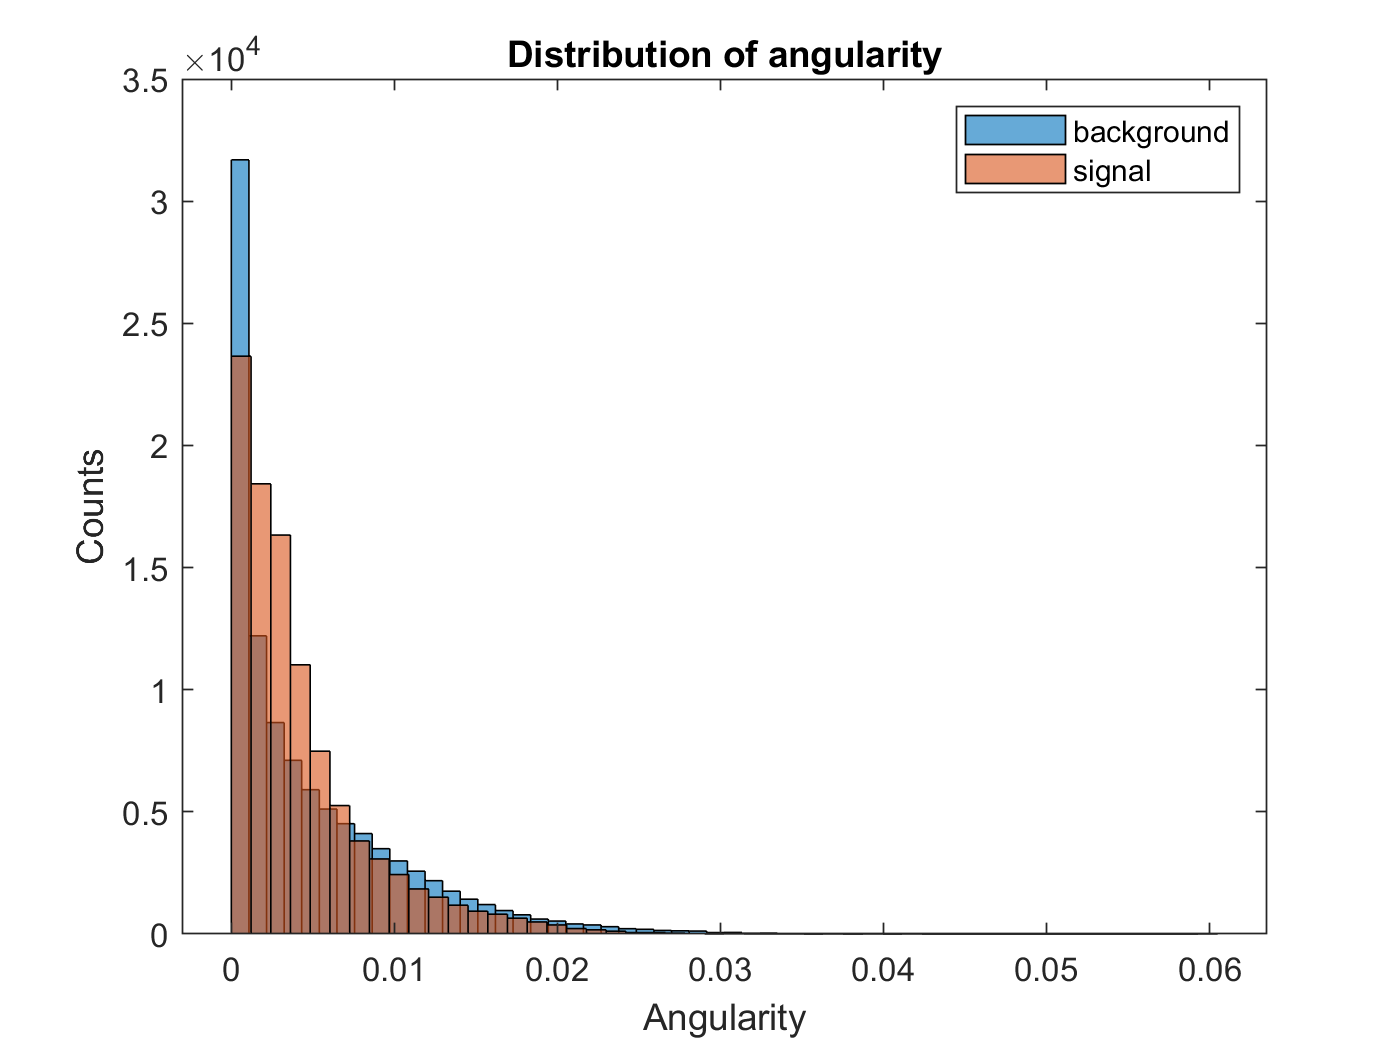

%angularity 
ang=background(8,:);
angs=signal(8,:);

histogram(ang,50)
hold on
histogram(angs,50)
legend('background','signal')
title('Distribution of angularity')
ylabel('Counts')
xlabel('Angularity')
hold off

Another exponential decay, with the signal still decaying faster but only slightly this time

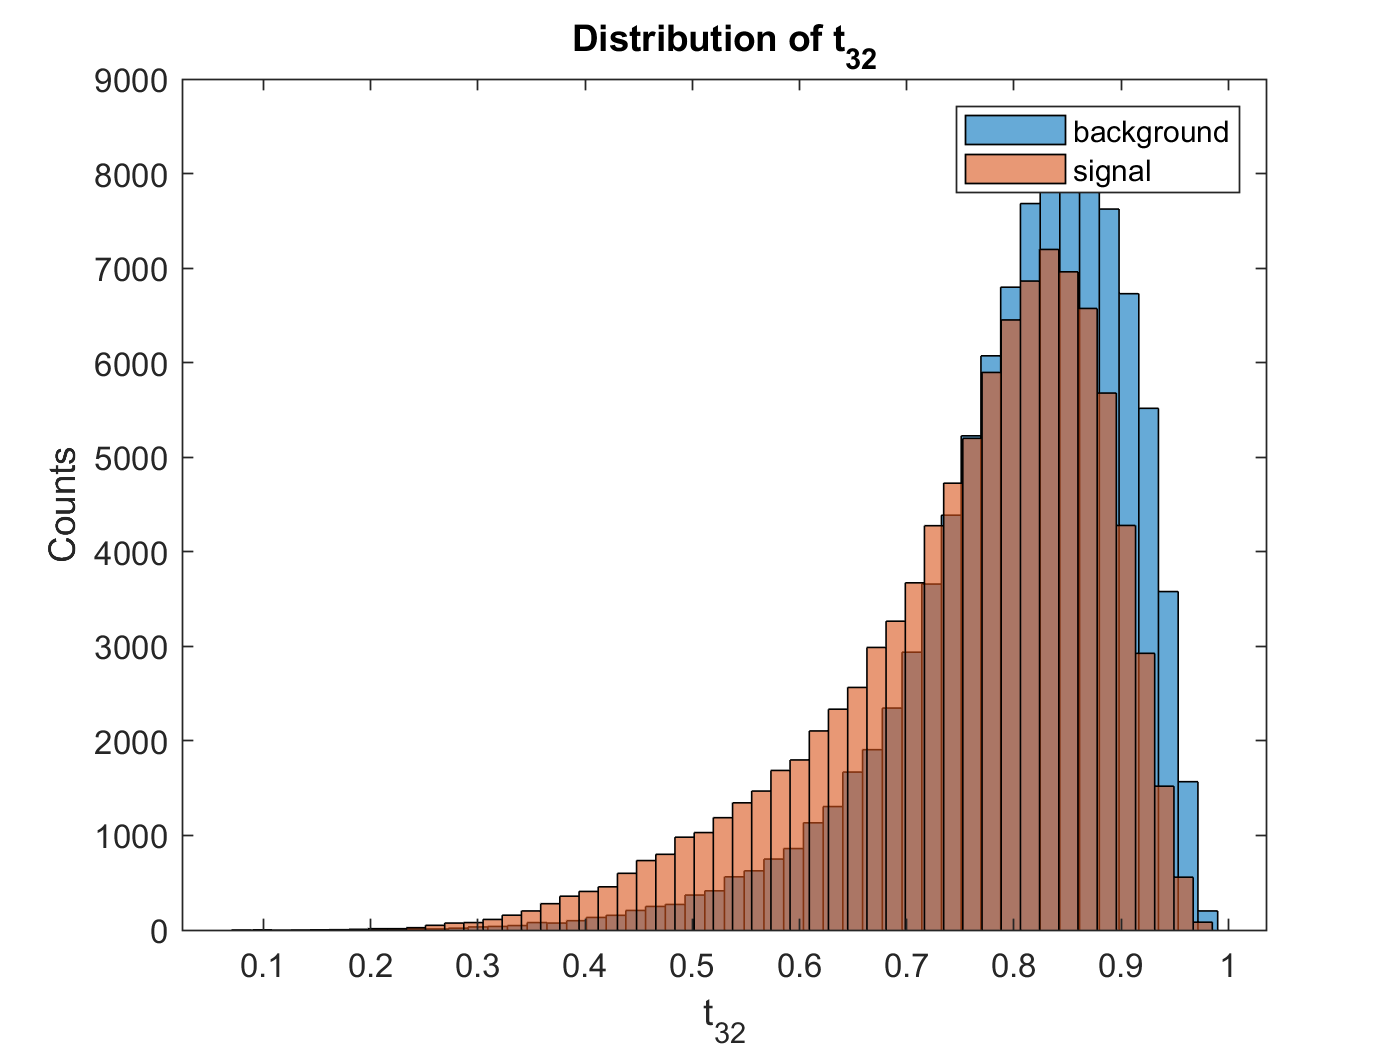

%plot t32, bc it would be the 3-2 ratio
t32=background(13,:);
t32s=signal(13,:);

histogram(t32,50)
hold on
histogram(t32s,50)
legend('background','signal')
title('Distribution of t_{32}')
ylabel('Counts')
xlabel('t_{32}')
hold off

Both distributions seem to have a similar shape, will want to keep an eye on it throught the next few labs. 

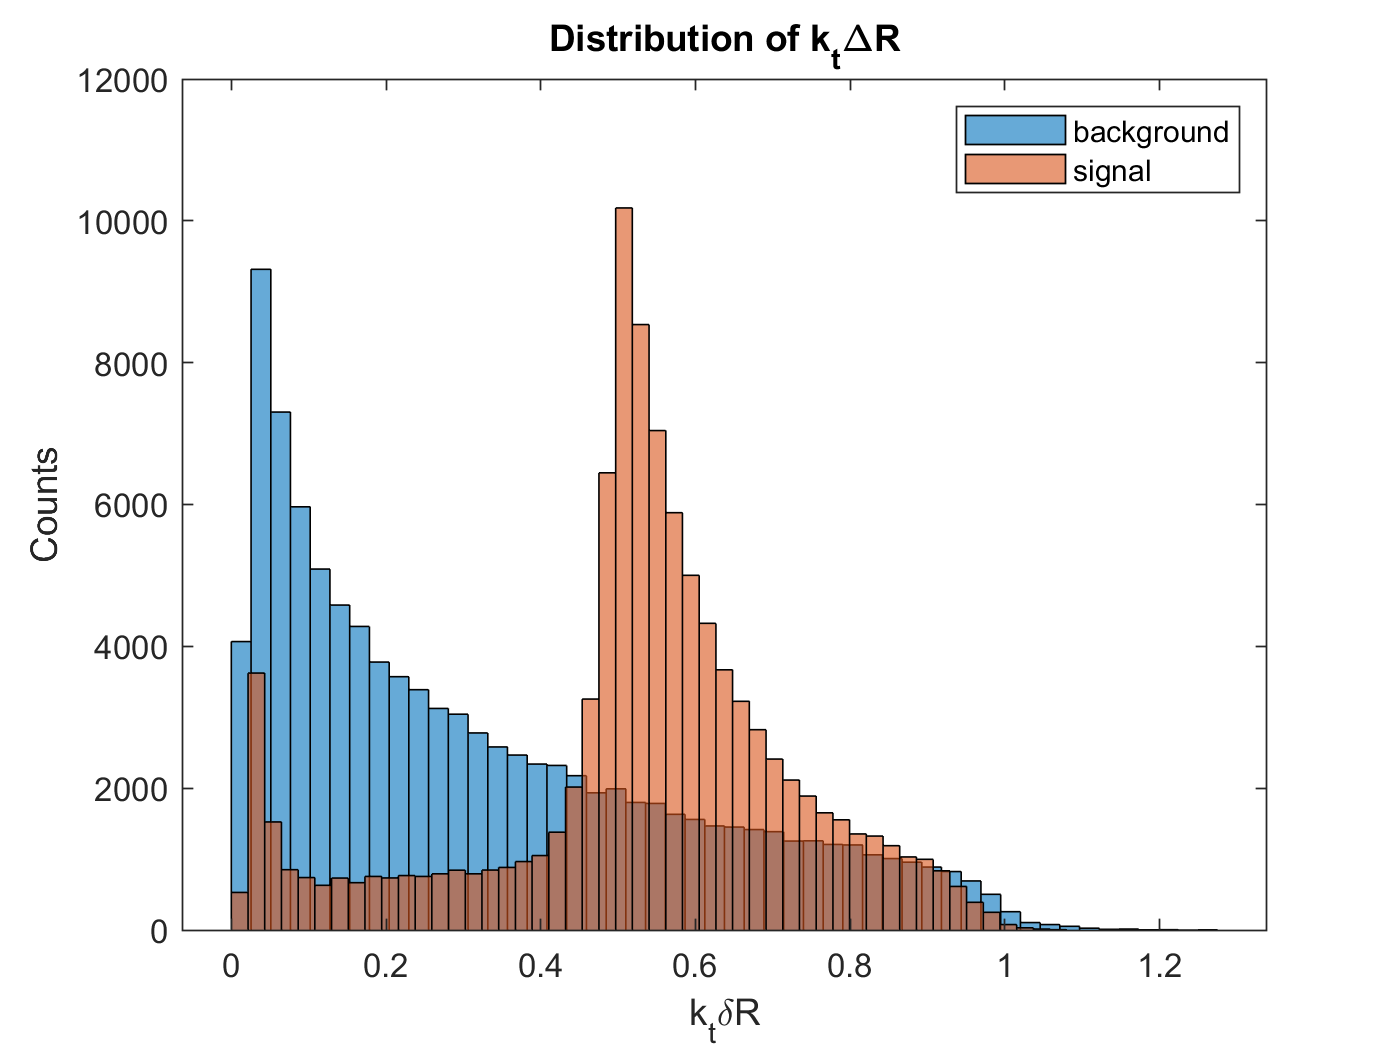

%ktdeltar plt
kt=background(14,:);
kts=signal(14,:);

histogram(kt,50)
hold on
histogram(kts,50)
legend('background','signal')
title('Distribution of k_t\DeltaR')
ylabel('Counts')
xlabel('k_{t}\deltaR')
hold off

Both distributions are weird, and I have no clue how I would want to approach this data set. 

## Conclusion of Plots

Now that we have plotted everything we can then see that there are certain relations that we can use as we continue further with this data set, the mass of particles, how the particles scatter after collision and so on. Since our end goal is to find or be able to claim a discovery of 5-sigma threshold of detection of a Higgs boson, we should figure which features will help use the most. 